# Atomic Spectroscopy

Project-based laboratory exercise in the course 

Atomic and Nuclear Physics with Applications (FAFF10)

#### *Names*

*Date*

# Introduction

This Matlab live script is meant to conduct the anaylsis as well as to present the results of the* atomic spectroscopy lab. *Generally all code provided is a guideline in order to get your analysis started. In case you want to use your own methods, feel free to change as much of the code as  you like. Each of the three tasks starts with the analysis of the data, followed by some calculations and ends with a discussion. The first task provides a lot of the code needed, whereas in the last part most of the coding is up to you. To get you started here are some general hints on how to use a Matlab live script:

- Make sure to be in the right Matlab folder, in order to access the external functions

- To run the current section, you can hit 'ctrl+enter'. The current section is indicated by the blue bar to the left.

- You can insert images, equations and other tools in the 'insert' tab above

- Change from code to text using 'ctrl+e'

# The spectrum of Hydrogen

### **Step 1:** Open your spectrum

Use the following dialog to open your file:

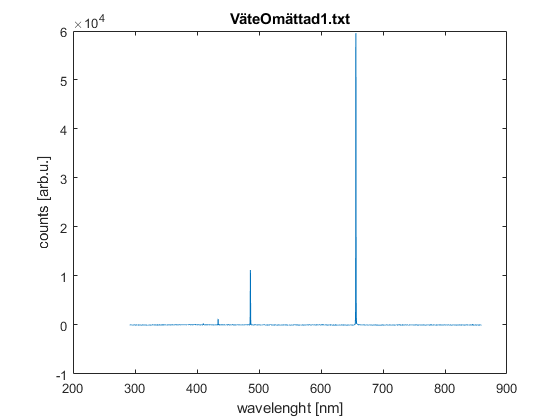

%%%% open file, the function 'open_spectrum' returns the wavlength vector, the background subtracted data vector and the file name as a string
[wl_hydrogen, data_hydrogen, file]=open_spectrum;

You can use the tools in the output window to navigate in the figure and preliminarily determine the position of the peaks. Use the magnifying tool to find all your peaks! When no tool is selected, hovering the mouse over the data will give you the current position. You can add annotations to the figure in the 'figure' tab above.  

### **Step 2:** Gaussian fit 

 Perform a Gaussian fit on the peaks in order to exactly determine the position of the peaks. First, you select a range around one of the peaks in the first line of the code and then you run the section. 

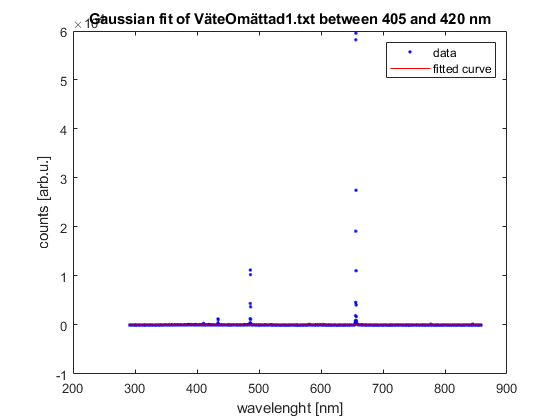

%%%% gaussian fit
range=[405;420];  % -> TODO <- adjust wavelength range around the peak you want to fit. Seperate using (;).

%%%%%%% NO NEED TO EDIT %%%%%%%
[~,index(1)] = min(abs(wl_hydrogen-range(1)));
[~,index(2)] = min(abs(wl_hydrogen-range(2)));
f=fit(wl_hydrogen(index(1):index(2)),data_hydrogen(index(1):index(2)),'gauss1');
plot(f,wl_hydrogen,data_hydrogen)
title(['Gaussian fit of ' file ' between ' num2str(range(1)) ' and ' num2str(range(2)) ' nm'],'Interpreter', 'none')
xlabel('wavelenght [nm]')
ylabel('counts [arb.u.]')

disp(['Extracted peak position: ' num2str(f.b1,5) ' nm'])

Extracted peak position: 410.23 nm


Repeat the fit for all the peaks that you found and insert the wavelength in the table below. Identify the transition using the [NIST data base](https://physics.nist.gov/PhysRefData/ASD/lines_form.html).

%%%% results table
hydrogen_wavelength=[410.23;434.08;486.15;656.25]; % -> TODO <- insert the extracted wavelength here. Add numbers by seperating them with ';' to the previous value.
hydrogen_transistions={'6';'5';'4';'3'}; % -> TODO <- compare the number with the nist database and identify the transition. Add names by seperating them with ';' to the previous value.

%%%%%%% NO NEED TO EDIT %%%%%%%
disp(table(hydrogen_wavelength,hydrogen_transistions,'VariableNames',{'Wavelength','Transition'}))

    Wavelength    Transition
    __________    __________

      410.23        {'6'}   
      434.08        {'5'}   
      486.15        {'4'}   
      656.25        {'3'}   



### **Step 3:** Calculate Rydberg constant

Use your extracted data to determine an experimental value for the [Rydberg constant](https://en.wikipedia.org/wiki/Rydberg_constant) of hydrogen using the following formula:


$$\frac{1}{\lambda_0 }=R_H \left(\frac{1}{n_1^2 -n_2^2 }\right)$$


where $n_1$and $n_2$ are two consecutive quantum numbers. Use the empty code box below to write your own code to extract the Rydberg constant.

%%%% your code starts here...
lambda=str2num(cell2mat(hydrogen_transistions))

lambda =      6
     5
     4
     3


R_h = zeros(4,1);
for i=1:numel(lambda)
    R_h(i)=1E9*(1/hydrogen_wavelength(i))/(0.25-(1/lambda(i)^2));
end
R_h_avg = sum(R_h)/numel(R_h)

R_h_avg = 1.0970e+07

### **Step 4: Discussion**

 Discuss your results, describe the procedure used for the experimental determination of the Rydberg constant and compare the experimental value for the Rydberg constant with the value from theory in a brief text below:

- *Your text starts here...*

*Vi har tagit ett spektrum. Vi identifierade de olika vågländstopparna och vilken övergång de motsvarade. Sedan sattes alla övergångar in i Rydbergs formel och ett genomsnitt på Rydbergs konstant togs. Värdet på Rydbergs konstant för väte är 1.09678*10^7 och det beräknade värdet vi fick blev 1.0970*10^7 vilket alltså är väldigt nära det teoretiska värdet.*

# The quantum defect

### **Step 1:** Open the full, unsaturated sodium spectrum. 

Identify as many sodium transitions corresponding to the different spectral lines, for which n=3 is the lower energy level, as possible. Use the Gaussian fit below and enter the values in the provided table further down.

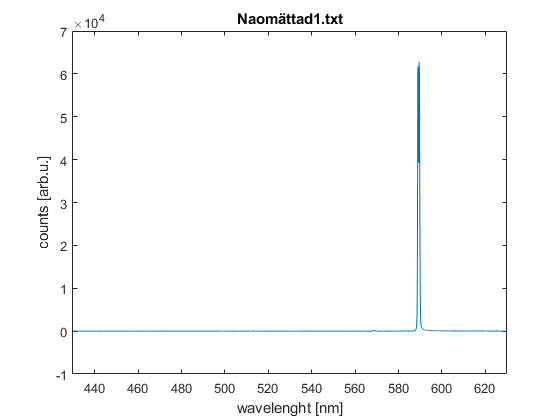

%%%% open file
[wl_sodium_full, data_sodium_full, file]=open_spectrum;
xlim([430 630])

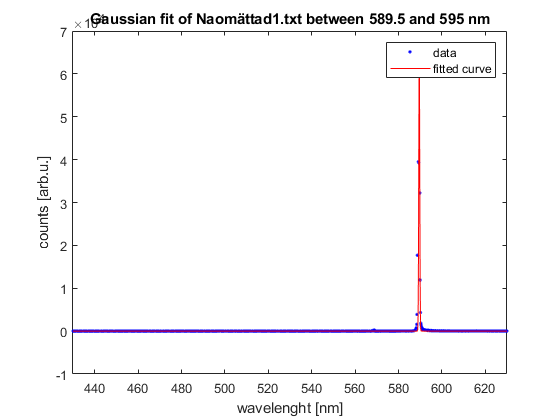

%%%% gaussian fit
range=[589.5,595];  % -> TODO <- adjust wavelength range around the peak you want to fit. Seperate using a comma (,).

%%%%%%% NO NEED TO EDIT %%%%%%%
[~,index(1)] = min(abs(wl_sodium_full-range(1)));
[~,index(2)] = min(abs(wl_sodium_full-range(2)));
f=fit(wl_sodium_full(index(1):index(2)),data_sodium_full(index(1):index(2)),'gauss1');
plot(f,wl_sodium_full,data_sodium_full)
title(['Gaussian fit of ' file ' between ' num2str(range(1)) ' and ' num2str(range(2)) ' nm'],'Interpreter', 'none')
xlabel('wavelenght [nm]')
ylabel('counts [arb.u.]')
xlim([430 630])

disp(['Extracted peak position: ' num2str(f.b1,5) ' nm'])

Extracted peak position: 589.56 nm


### **Step 2:** Open a saturated spectrum

Identify all the small peaks, which are otherwise hidden in the noise. Again try to find all transitions, for which n=3 is the lower energy level and enter the values in the provided table further down.

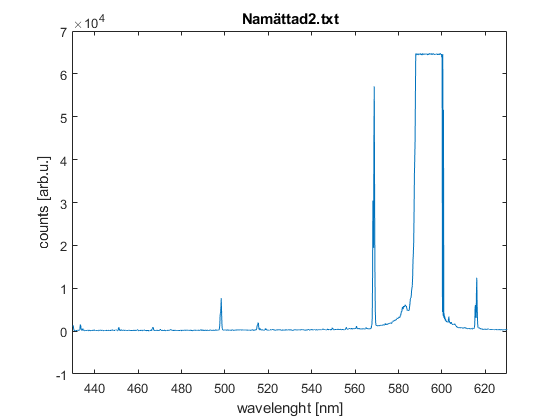

%%%% open file
[wl_sodium_zoom, data_sodium_zoom, file]=open_spectrum;
xlim([430 630])

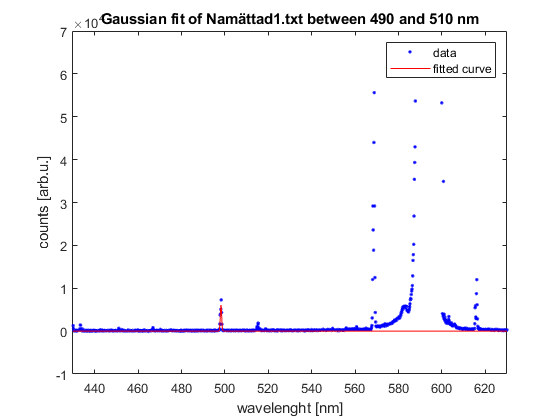

%%%% gaussian fit
range=[490,510];  % -> TODO <- adjust wavelength range around the peak you want to fit. Seperate using a comma (,).

%%%%%%% NO NEED TO EDIT %%%%%%%
[~,index(1)] = min(abs(wl_sodium_zoom-range(1)));
[~,index(2)] = min(abs(wl_sodium_zoom-range(2)));
f=fit(wl_sodium_zoom(index(1):index(2)),data_sodium_zoom(index(1):index(2)),'gauss1');
plot(f,wl_sodium_zoom,data_sodium_zoom)
title(['Gaussian fit of ' file ' between ' num2str(range(1)) ' and ' num2str(range(2)) ' nm'],'Interpreter', 'none')
xlabel('wavelenght [nm]')
ylabel('counts [arb.u.]')
xlim([430 630])

disp(['Extracted peak position: ' num2str(f.b1,5) ' nm'])

Extracted peak position: 498.2 nm


Fill in your results from the previous analysis in the table below. Intentify the transistion, for which n=3 is the lower energy level, using the [NIST data base](https://physics.nist.gov/PhysRefData/ASD/lines_form.html).

### **Step 3:** Calculate experimental values for the quantum defect

Calculate experimental values for the quantum defect $\delta =n-n^*$, where $n^* =\sqrt{\frac{R_{\textrm{Na}} \zeta^2 }{E_{\textrm{ion}} -E_{\textrm{exe}} }}$ of all identified energy levels. Find more information about the formula as well as the exact values for the constants in your textbooks, for example: *Foot, C. J. Atomic Physics. Oxford: Oxford University Press, 2005  * or   *A. Thorne, U. Litzén, S. Johansson. Spectrophysics: Principles and Applications. Media-Tryck Lund, 2007.*

%%%% results table
sodium_wavelength=[498.2;589.31;568.7;615.93]; % -> TODO <- insert the extracted wavelength for all peaks here. Add more values by separating them with a semicolon (;).
sodium_upperlevel={'2p5d';'2p3p';'2p4d';'2p5s'}; % -> TODO <- compare the number with the nist database and identify the transition, insert the upper lever here
sodium_lowerlevel={'2p3p';'2p3s';'2p3p';'2p3p'}; % -> TODO <- compare the number with the nist database and identify the transition, insert the lower lever here

%%%% -> TODO <- Here you have space to develop your own code to calculate the quantum defect
format long
hc = 6.626*10^(-34)*(2.998*10^8);
R_na=1.0974*10^7

R_na =     10974000


zeta=sqrt(hc)

zeta =      4.456988669494236e-13


E= (hc/10^(-9))*(1./sodium_wavelength); 
E_ion=[5.1391*1.6022*10^(-19), 5.1391*1.6022*10^(-19)-hc/(589.31*10^(-9))];
n_ = 0;

sodium_quantumdefect_exp=[NaN;NaN;NaN;NaN];

for i=1:numel(E)
    index = contains(sodium_lowerlevel{i}, '3p')+1
    n_ = sqrt(R_na*hc)/sqrt(E_ion(index)-E(i));
    sodium_quantumdefect_exp(i) = str2double(sodium_upperlevel{i}(3))-n_;
end

index =      2


ans =      5


index =      1


ans =      3


index =      2


ans =      4


index =      2


ans =      5


   0.010661334042711
   0.882755096193225
   0.011013605574119
   1.351734846436421



 % -> TODO <- insert the calculated quantum defect here
sodium_quantumdefect_theo=[0.014;0.86;0.014;1.37]; % -> TODO <- insert the theoretical quantum defect here

%%%%%%% NO NEED TO EDIT %%%%%%%
disp(table(sodium_wavelength,char(sodium_upperlevel),char(sodium_lowerlevel),sodium_quantumdefect_exp,sodium_quantumdefect_theo,...
    'VariableNames',{'Wavelength [nm]','Upper level','Lower level','Calculated quantum defect','Theoretical quantum defect'}))

    Wavelength [nm]    Upper level    Lower level    Calculated quantum defect    Theoretical quantum defect
    _______________    ___________    ___________    _________________________    __________________________

         498.2            2p5d           2p3p           0.0106613340427106                  0.014           
        589.31            2p3p           2p3s            0.882755096193225                   0.86           
         568.7            2p4d           2p3p           0.0110136055741186                  0.014           
        615.93            2p5s           2p3p             1.35173484643642                   1.37           



### **Step 4:** Calculate the vacuum wavelength for the 3p – 8d transition

Estimate the vacuum wavelength for the transition 3p – 8d in sodium as accurately as possible.

Enter the formula that you use here (you can write LaTex code):


$$\$$


Use the empty code box below to write your own code to calculate the vacuum wavelength:

%%%% your code starts here
delta = 0.014;
n = 8;
lambda = (hc/(E_ion(2)-(R_na*hc/(n-delta)^2)))/(1*10^(-9));
disp("Vacuum wavelength is: " + lambda)

Vacuum wavelength is: 439.3686


### **Step 5: Discussion**

Discuss your results. Comment, in particular, on the internal order of the energy levels corresponding to different orbitals, and on the underlying physics.Descripe the procedure used for the experimental determination of the quantum defects and the vacuum wavelength for the transition 3p – 8d in sodium, together with the actual calculations. Compare the experimentally determined quantum defects with the ones calculated from the tabulated energy levels.

- *Your text starts here...*

*The valence electron in Sodium is in the *$1s^22s^22p^63s^1$ orbital. The ionization energy of Sodium is thus the energy required to excite this electron. The energy levels higher than this, such as the ..$3p^1$ orbital thus represent excited electons

Valens elektronen i Natrium är i $1s^22s^22p^63s^1$ orbitalen. Joniseringsenergin för Natrium motsvarar alltså energinivån för denna valenselektron. Alla orbitaler högre som t.ex. ...$3p^1$orbitalen motsvarar alltså ett exciterat tillstånd. I detta fall blir joniseringsenergin övergångsenergin mellan $..3p^1\to3s^1$+ joniseringsenergin för valenselektronen i grundtillståndet. Kvantdefekten gör att energitillstånden hamnar på en lite lägre nivå än vad Rydbergs formel ger och beror främst på rörelsemängdsmomentskvanttalet l. Denna defekt är som störst för $s$  eller $l=0$ orbitalen och minskar för högre l. Denna defekt beräknades genom att ta ett spektrum på natrium och 

# Fine structure

### Step 1: Open file and identify peaks

In this last part you are supposed to conduct more of the analysis on your own. Try to modify the code in order to extract peak height and position. For overlapping peaks you can use a double- or triple-gaussian fit instead.

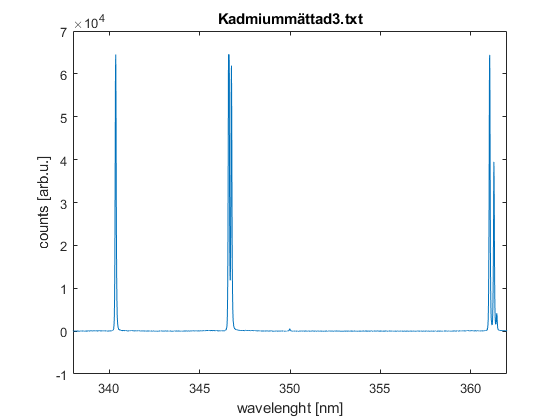

%%%% open file
[wl_cadmium, data_cadmium, file]=open_spectrum;
xlim([338 362])

%%%% gaussian fit
range=[360.5,363];  % -> TODO <- adjust wavelength range around the peak you want to fit. Seperate using a comma (,).
[~,index(1)] = min(abs(wl_cadmium-range(1)));
[~,index(2)] = min(abs(wl_cadmium-range(2)));
f=fit(wl_cadmium(index(1):index(2)),data_cadmium(index(1):index(2)),'gauss3') % -> TODO <- try to modify the fit function to fit a double- or triple-gaussian for overlapping peaks

f =      General model Gauss3:
     f(x) = 
              a1*exp(-((x-b1)/c1)^2) + a2*exp(-((x-b2)/c2)^2) + 
              a3*exp(-((x-b3)/c3)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.473e+04  (6.384e+04, 6.562e+04)
       b1 =         361  (361, 361)
       c1 =      0.0388  (0.03817, 0.03942)
       a2 =   3.774e+04  (3.683e+04, 3.865e+04)
       b2 =       361.3  (361.3, 361.3)
       c2 =      0.0372  (0.03611, 0.03828)
       a3 =        3467  (2750, 4184)
       b3 =       361.4  (361.4, 361.4)
       c3 =     0.06107  (0.04585, 0.07629)

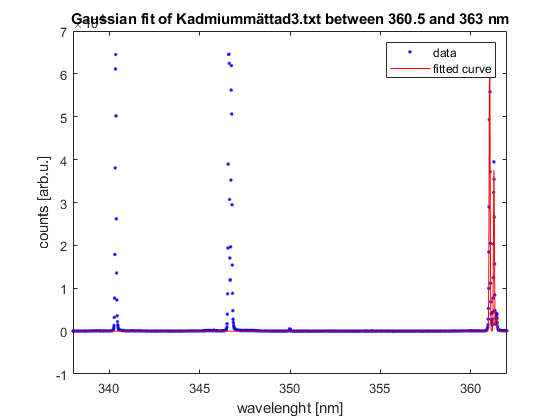

plot(f,wl_cadmium,data_cadmium)
title(['Gaussian fit of ' file ' between ' num2str(range(1)) ' and ' num2str(range(2)) ' nm'],'Interpreter', 'none')
xlabel('wavelenght [nm]')
ylabel('counts [arb.u.]')
xlim([338 362])

disp(['Extracted peak position: ' num2str(f.b1,5) 'nm ' num2str(f.b2, 5) 'nm ' num2str(f.b3, 5) 'nm ', 'Extracted peak height: ' num2str(f.a1, 5) ' ' num2str(f.a2, 5) ' ' num2str(f.a3, 5)]) % -> TODO <- here you need to extract the peak height in addition to the position.

Extracted peak position: 361.04nm 361.28nm 361.43nm Extracted peak height: 64727 37738 3467


### Step 2: Conduct the analysis

- Determine the vacuum wavelengths of as many lines as possible in the wavelength range 340-362 nm of your collected spectra.

- Identify the cadmium transitions corresponding to the different spectral lines and make sure that you find a multiplet with in total six transitions.

- Determine the relative intensities of the six lines in the multiplet. 

- Determine the relative energies of the fine structure levels of the two involved triplets

Use the empty code box below to write your own code. Create a table for all the identified spectral lines including the vacuum wavelengths, the energy levels involved in the transitions and the relative intensities of the transitions. Additionally present the relative energies of the fine structure levels of the two involved triplets. Include a sketch of the energy level diagram where the identified transitions are marked (Images can be imported under the 'Insert' tab above).

%%%% your code starts here
cadmium_wavelengths=[340.36;346.62;346.76;361.04;361.28;361.43];
cadmium_transitions = {'5d-5p';'5d-5p';'5d-5p';'5d-5p';'5p-5d';'5p-5d'};
cadmium_intensities = [35070;46685;31642;64727;37738;3467];
disp(table(cadmium_wavelengths, char(cadmium_transitions),cadmium_intensities,'VariableNames',{'Wavelength','Transition', 'Intensity'}))

    Wavelength    Transition    Intensity
    __________    __________    _________

      340.36        5d-5p         35070  
      346.62        5d-5p         46685  
      346.76        5d-5p         31642  
      361.04        5d-5p         64727  
      361.28        5p-5d         37738  
      361.43        5p-5d          3467  



### Step 3: Discussion

Discuss briefly all the figures, tables and diagrams and answer to the following questions:

- Is the fine structure of the studied terms in agreement with the Landé interval rule. If not, what is a possible reason for this?

- Do the relative intensities  fulfill the sum rule for multiplets? If not, what is a possible reason for this?

- The hardly visible line around 350 nm correspond to a transition between a triplet and a singlet, which is not allowed in the LS coupling scheme. What transition is this, and why is it at all visible?

*Your text starts here...*